# EVALUATENET

Evaluate the network programmatically.

## Create and train the network

createNNet

## Predict activity based on model

This returns a score, and maximum score is the class

scoreTest = net(X(:,tr.testInd));
[~,yPred] = max(scoreTest);
yPred = yPred'; % row -> column

## Evaluate classification with confusion matrix

HDtest = heartdataAll.HeartDisease(tr.testInd);
yT = dummyvar(HDtest)';
yP = dummyvar(categorical(yPred,1:2))';

Converting to categorical first allows specification of the possible classes, so yP will have the same dimensions are yT, even if not all the classes are predicted.

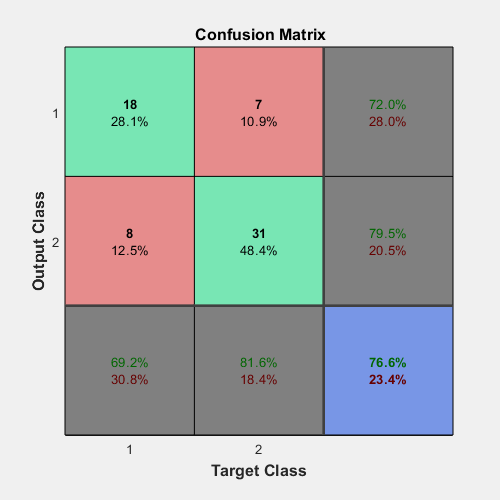

figure
plotconfusion(yT,yP)

## Determine validation error

validErr = 100*nnz(yPred ~= double(HDtest))/length(HDtest)

validErr = 23.4375